# My datastore

clc;
close all;
clear variables;

## Creating a datastore for my images

imds = imageDatastore(fullfile(pwd, 'data', 'raw'));
raw_images = readall(imds);

### Display raw images

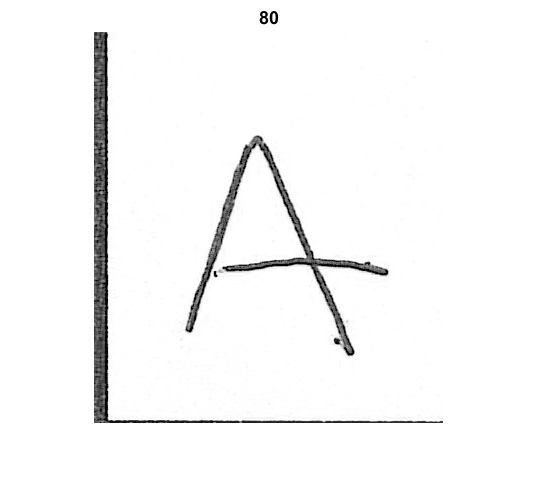

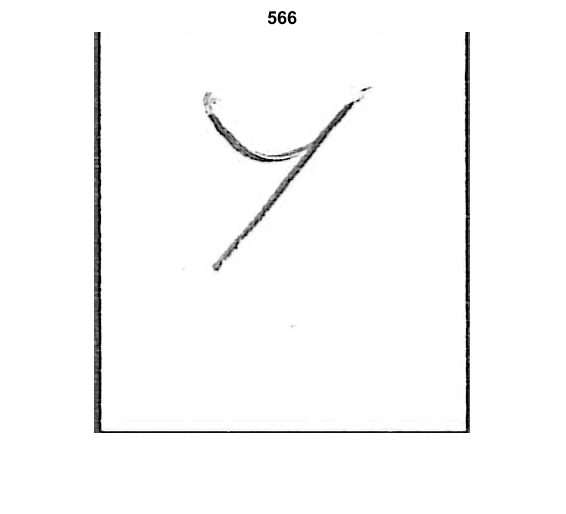

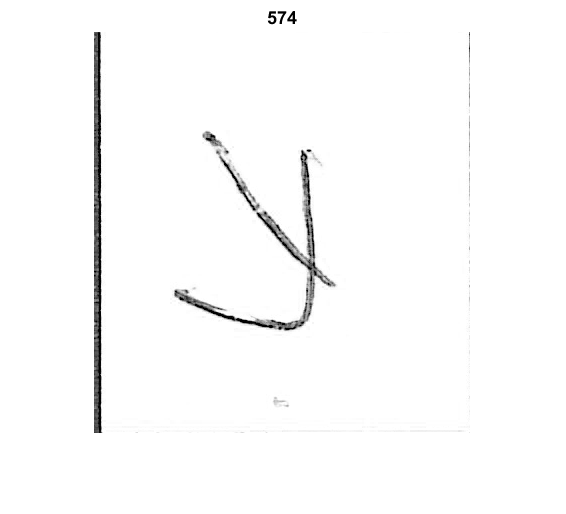

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(raw_images{rand_int})
    title(rand_int)
end

## Preprocessing images

bin_threshold = 0.9;
target_size = [224,224];

preprocessed_imds = transform(imds, @(x) imresize(x, target_size));
% gaussian filter?
preprocessed_imds = transform(preprocessed_imds, @(x) binarization(x, bin_threshold));
% median filter?
preprocessed_imds = transform(preprocessed_imds, @edge_removal);


N = length(imds.Files);
preprocessed_images = cell(N, 1);
for i = 1:N
    preprocessed_images{i} = read(preprocessed_imds);
end

### Display preprocessed images

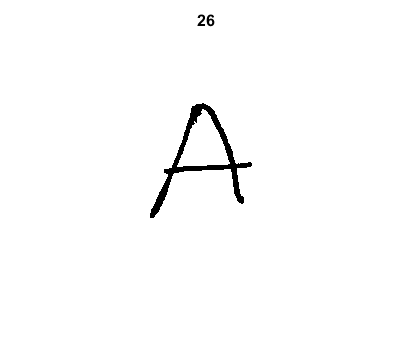

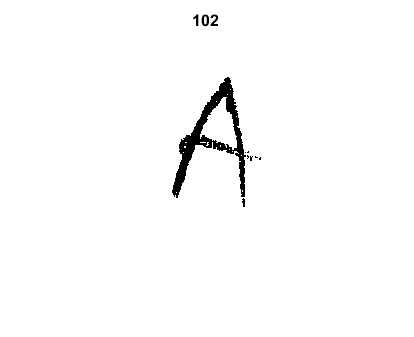

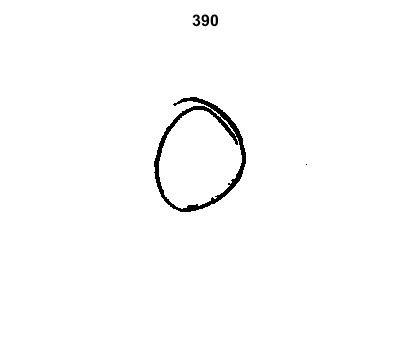

for i=1:3
    figure();
    rand_int = randi(length(imds.Files));
    imshow(preprocessed_images{rand_int})
    title(rand_int)
end